original_bridge.output
original_bridge.run

ans = -1.0737e+09

% 运行一次即可，无需重复运行
time_before = datetime('now');
num_GirderNodes = [];
[OutputMethod_clone,num_GirderNodes] = analyzeInfluenceLine(original_bridge.OutputMethod,num_GirderNodes);

ans = 8

ans = 8

time_after = datetime('now');
time_after - time_before

ans = duration
   00:03:34


% 可以不断修改需要检测的项目，然后重复运行
num_MonitoredNodes = 222;
num_MonitoredElems_Link = 1310;
num_MonitoredElems_Beam = 190;
data = getInfluenceLineResult(original_bridge.OutputMethod,OutputMethod_clone,num_GirderNodes,num_MonitoredNodes,num_MonitoredElems_Link,num_MonitoredElems_Beam);

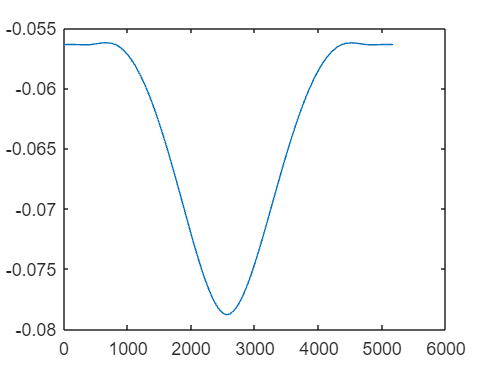

x = 0:7.5:690*7.5;
plot(x,data.Deformation_Z')

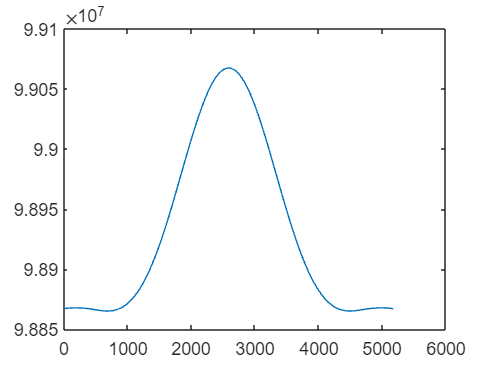

plot(x,data.Fx_link')

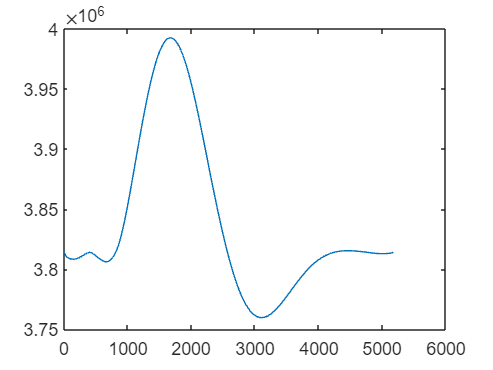

plot(x,data.Fxi_beam')

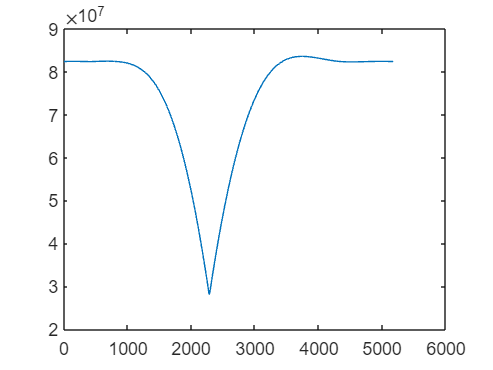

plot(x,data.Myi_beam')